% Initialization
Lls = 0.27527e-3;
Llr = 0.27527e-3;
 Lm = 3.6514e-3;
Lms =(2/3)*Lm;
Lmr = Lms;
Lsr = Lmr;
dt = 0.0001; % time step
tend = 10; % end time
t= 0:dt:tend;
[n, size_t] = size(t);
theta = linspace(0, 2*pi, size_t);

% Preallocate arrays for storage
Labcs_values = zeros(3, 3, size_t);
Labcr_values = zeros(3, 3, size_t);
Labcsr_values = zeros(3, 3, size_t);
Labcrs_values = zeros(3, 3, size_t);
Labcsrdiff_values = zeros(3, 3, size_t);
Labcrsdiff_values = zeros(3, 3, size_t);

% Calculate matrix values for each theta
for i = 2:size_t
    Labcs_values(:,:,i) = [Lls+Lms, -0.5*Lms, -0.5*Lms; -0.5*Lms, Lls+Lms, -0.5*Lms; -0.5*Lms, -0.5*Lms, Lls+Lms];
    Labcr_values(:,:,i) = [Llr+Lmr, -0.5*Lmr, -0.5*Lmr; -0.5*Lmr, Llr+Lmr, -0.5*Lmr; -0.5*Lmr, -0.5*Lmr, Llr+Lmr];
    Labcsr_values(:,:,i) = [Lsr*cos(theta(i-1)), Lsr*cos(theta(i-1)+(2*pi/3)), Lsr*cos(theta(i-1)-(2*pi/3));
                            Lsr*cos(theta(i-1)-2*pi/3), Lsr*cos(theta(i-1)), Lsr*cos(theta(i-1)+(2*pi/3));
                            Lsr*cos(theta(i-1)+(2*pi/3)), Lsr*cos(theta(i-1)-(2*pi/3)), Lsr*cos(theta(i-1))];
    Labcrs_values(:,:,i) = Labcsr_values(:,:,i)';
    Labcsrdiff_values(:,:,i) = [-Lsr*sin(theta(i-1)), -Lsr*sin(theta(i-1)+(2*pi/3)), -Lsr*sin(theta(i-1)-(2*pi/3));
                                -Lsr*sin(theta(i-1)-2*pi/3), -Lsr*sin(theta(i-1)), -Lsr*sin(theta(i-1)+(2*pi/3));
                                -Lsr*sin(theta(i-1)+(2*pi/3)), -Lsr*sin(theta(i-1)-(2*pi/3)), -Lsr*sin(theta(i-1))];
    Labcrsdiff_values(:,:,i) = Labcsrdiff_values(:,:,i)';
end
calculated_amplitude = (max(squeeze(Labcsr_values(1,1,:))) - min(squeeze(Labcsr_values(1,1,:)))) / 2

calculated_amplitude = 0.0024

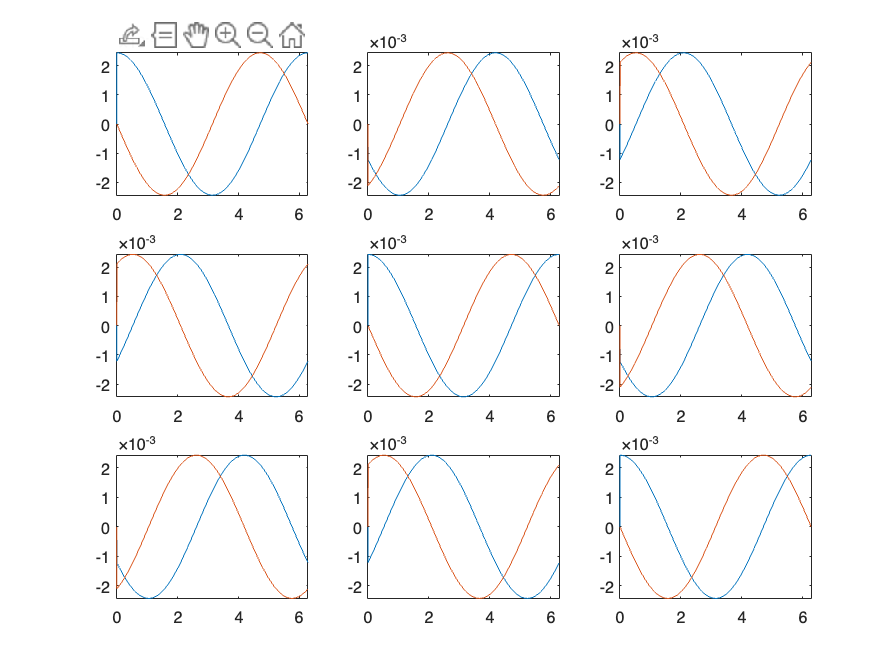


% Plotting
for i = 1:3
    for j = 1:3
        subplot(3,3,(i-1)*3+j);
        % Choose the appropriate matrix based on i and j. This is just an example for Labcs_values and Labcsrdiff_values.
        plot(theta, squeeze(Labcsr_values(i,j,:)));
        hold on;
        plot(theta, squeeze(Labcsrdiff_values(i,j,:)));
        hold off;
    end
end

% 
